# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

Out-of-sample forecasts are from 2018-5-18 to 2019-5-18. Rolling estimation window size is 750 and forecast one-day ahead.

The difference between this file and "exercise_VolForecastRV_1_0_1.mlx" in folder "Volatility_predict_1_0_1_1Y_WS750" is we want to change forecast time to 2018-05-18 to 2019-05-18 and we want to omit RSGARCH

We separate GARCH, GJR, HAR and HAR-a into different functions to calculate corresponding volatility, VolFcst_GARCH, VolFcst_GJR and VolFcst_HAR. Then you have to use Save_VolFcst_to_Mat to save results.

clear,clc

addpath("Functions/")
tic
Read_Name='SP500_0608.xlsx';
Time_Outsample=[2018,05,18;2019,05,18];
rv=get_rv(Read_Name,Time_Outsample);
Index_Name = 'SP500';
Working_Date = '20240321';
Window_Size = 1000;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: i=64
CPGARCH: i=65
CPGARCH: i=66
CPGARCH: i=67
CPGARCH: i=68
CPGARCH: i=69
CPGARCH: i=70
CPGARCH: i=71
CPGARCH: i=72
C

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);

GJR: i=1
GJR: i=2
GJR: i=3
GJR: i=4
GJR: i=5
GJR: i=6
GJR: i=7
GJR: i=8
GJR: i=9
GJR: i=10
GJR: i=11
GJR: i=12
GJR: i=13
GJR: i=14
GJR: i=15
GJR: i=16
GJR: i=17
GJR: i=18
GJR: i=19
GJR: i=20
GJR: i=21
GJR: i=22
GJR: i=23
GJR: i=24
GJR: i=25
GJR: i=26
GJR: i=27
GJR: i=28
GJR: i=29
GJR: i=30
GJR: i=31
GJR: i=32
GJR: i=33
GJR: i=34
GJR: i=35
GJR: i=36
GJR: i=37
GJR: i=38
GJR: i=39
GJR: i=40
GJR: i=41
GJR: i=42
GJR: i=43
GJR: i=44
GJR: i=45
GJR: i=46
GJR: i=47
GJR: i=48
GJR: i=49
GJR: i=50
GJR: i=51
GJR: i=52
GJR: i=53
GJR: i=54
GJR: i=55
GJR: i=56
GJR: i=57
GJR: i=58
GJR: i=59
GJR: i=60
GJR: i=61
GJR: i=62
GJR: i=63
GJR: i=64
GJR: i=65
GJR: i=66
GJR: i=67
GJR: i=68
GJR: i=69
GJR: i=70
GJR: i=71
GJR: i=72
GJR: i=73
GJR: i=74
GJR: i=75
GJR: i=76
GJR: i=77
GJR: i=78
GJR: i=79
GJR: i=80
GJR: i=81
GJR: i=82
GJR: i=83
GJR: i=84
GJR: i=85
GJR: i=86
GJR: i=87
GJR: i=88
GJR: i=89
GJR: i=90
GJR: i=91
GJR: i=92
GJR: i=93
GJR: i=94
GJR: i=95
GJR: i=96
GJR: i=97
GJR: i=98
GJR: i=99
GJR: i=100
GJR: i=1

results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=1
CPGJR: i=2
CPGJR: i=3
CPGJR: i=4
CPGJR: i=5
CPGJR: i=6
CPGJR: i=7
CPGJR: i=8
CPGJR: i=9
CPGJR: i=10
CPGJR: i=11
CPGJR: i=12
CPGJR: i=13
CPGJR: i=14
CPGJR: i=15
CPGJR: i=16
CPGJR: i=17
CPGJR: i=18
CPGJR: i=19
CPGJR: i=20
CPGJR: i=21
CPGJR: i=22
CPGJR: i=23
CPGJR: i=24
CPGJR: i=25
CPGJR: i=26
CPGJR: i=27
CPGJR: i=28
CPGJR: i=29
CPGJR: i=30
CPGJR: i=31
CPGJR: i=32
CPGJR: i=33
CPGJR: i=34
CPGJR: i=35
CPGJR: i=36
CPGJR: i=37
CPGJR: i=38
CPGJR: i=39
CPGJR: i=40
CPGJR: i=41
CPGJR: i=42
CPGJR: i=43
CPGJR: i=44
CPGJR: i=45
CPGJR: i=46
CPGJR: i=47
CPGJR: i=48
CPGJR: i=49
CPGJR: i=50
CPGJR: i=51
CPGJR: i=52
CPGJR: i=53
CPGJR: i=54
CPGJR: i=55
CPGJR: i=56
CPGJR: i=57
CPGJR: i=58
CPGJR: i=59
CPGJR: i=60
CPGJR: i=61
CPGJR: i=62
CPGJR: i=63
CPGJR: i=64
CPGJR: i=65
CPGJR: i=66
CPGJR: i=67
CPGJR: i=68
CPGJR: i=69
CPGJR: i=70
CPGJR: i=71
CPGJR: i=72
CPGJR: i=73
CPGJR: i=74
CPGJR: i=75
CPGJR: i=76
CPGJR: i=77
CPGJR: i=78
CPGJR: i=79
CPGJR: i=80
CPGJR: i=81
CPGJR: i=82
CPGJR: i=83
CPGJR: i=84
C

results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);

HAR: i=1
HAR: i=2
HAR: i=3
HAR: i=4
HAR: i=5
HAR: i=6
HAR: i=7
HAR: i=8
HAR: i=9
HAR: i=10
HAR: i=11
HAR: i=12
HAR: i=13
HAR: i=14
HAR: i=15
HAR: i=16
HAR: i=17
HAR: i=18
HAR: i=19
HAR: i=20
HAR: i=21
HAR: i=22
HAR: i=23
HAR: i=24
HAR: i=25
HAR: i=26
HAR: i=27
HAR: i=28
HAR: i=29
HAR: i=30
HAR: i=31
HAR: i=32
HAR: i=33
HAR: i=34
HAR: i=35
HAR: i=36
HAR: i=37
HAR: i=38
HAR: i=39
HAR: i=40
HAR: i=41
HAR: i=42
HAR: i=43
HAR: i=44
HAR: i=45
HAR: i=46
HAR: i=47
HAR: i=48
HAR: i=49
HAR: i=50
HAR: i=51
HAR: i=52
HAR: i=53
HAR: i=54
HAR: i=55
HAR: i=56
HAR: i=57
HAR: i=58
HAR: i=59
HAR: i=60
HAR: i=61
HAR: i=62
HAR: i=63
HAR: i=64
HAR: i=65
HAR: i=66
HAR: i=67
HAR: i=68
HAR: i=69
HAR: i=70
HAR: i=71
HAR: i=72
HAR: i=73
HAR: i=74
HAR: i=75
HAR: i=76
HAR: i=77
HAR: i=78
HAR: i=79
HAR: i=80
HAR: i=81
HAR: i=82
HAR: i=83
HAR: i=84
HAR: i=85
HAR: i=86
HAR: i=87
HAR: i=88
HAR: i=89
HAR: i=90
HAR: i=91
HAR: i=92
HAR: i=93
HAR: i=94
HAR: i=95
HAR: i=96
HAR: i=97
HAR: i=98
HAR: i=99
HAR: i=100
HAR: i=1

results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=1
CPHAR: i=2
CPHAR: i=3
CPHAR: i=4
CPHAR: i=5
CPHAR: i=6
CPHAR: i=7
CPHAR: i=8
CPHAR: i=9
CPHAR: i=10
CPHAR: i=11
CPHAR: i=12
CPHAR: i=13
CPHAR: i=14
CPHAR: i=15
CPHAR: i=16
CPHAR: i=17
CPHAR: i=18
CPHAR: i=19
CPHAR: i=20
CPHAR: i=21
CPHAR: i=22
CPHAR: i=23
CPHAR: i=24
CPHAR: i=25
CPHAR: i=26
CPHAR: i=27
CPHAR: i=28
CPHAR: i=29
CPHAR: i=30
CPHAR: i=31
CPHAR: i=32
CPHAR: i=33
CPHAR: i=34
CPHAR: i=35
CPHAR: i=36
CPHAR: i=37
CPHAR: i=38
CPHAR: i=39
CPHAR: i=40
CPHAR: i=41
CPHAR: i=42
CPHAR: i=43
CPHAR: i=44
CPHAR: i=45
CPHAR: i=46
CPHAR: i=47
CPHAR: i=48
CPHAR: i=49
CPHAR: i=50
CPHAR: i=51
CPHAR: i=52
CPHAR: i=53
CPHAR: i=54
CPHAR: i=55
CPHAR: i=56
CPHAR: i=57
CPHAR: i=58
CPHAR: i=59
CPHAR: i=60
CPHAR: i=61
CPHAR: i=62
CPHAR: i=63
CPHAR: i=64
CPHAR: i=65
CPHAR: i=66
CPHAR: i=67
CPHAR: i=68
CPHAR: i=69
CPHAR: i=70
CPHAR: i=71
CPHAR: i=72
CPHAR: i=73
CPHAR: i=74
CPHAR: i=75
CPHAR: i=76
CPHAR: i=77
CPHAR: i=78
CPHAR: i=79
CPHAR: i=80
CPHAR: i=81
CPHAR: i=82
CPHAR: i=83
CPHAR: i=84
C

results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=1
ICPHAR: i=2
ICPHAR: i=3
ICPHAR: i=4
ICPHAR: i=5
ICPHAR: i=6
ICPHAR: i=7
ICPHAR: i=8
ICPHAR: i=9
ICPHAR: i=10
ICPHAR: i=11
ICPHAR: i=12
ICPHAR: i=13
ICPHAR: i=14
ICPHAR: i=15
ICPHAR: i=16
ICPHAR: i=17
ICPHAR: i=18
ICPHAR: i=19
ICPHAR: i=20
ICPHAR: i=21
ICPHAR: i=22
ICPHAR: i=23
ICPHAR: i=24
ICPHAR: i=25
ICPHAR: i=26
ICPHAR: i=27
ICPHAR: i=28
ICPHAR: i=29
ICPHAR: i=30
ICPHAR: i=31
ICPHAR: i=32
ICPHAR: i=33
ICPHAR: i=34
ICPHAR: i=35
ICPHAR: i=36
ICPHAR: i=37
ICPHAR: i=38
ICPHAR: i=39
ICPHAR: i=40
ICPHAR: i=41
ICPHAR: i=42
ICPHAR: i=43
ICPHAR: i=44
ICPHAR: i=45
ICPHAR: i=46
ICPHAR: i=47
ICPHAR: i=48
ICPHAR: i=49
ICPHAR: i=50
ICPHAR: i=51
ICPHAR: i=52
ICPHAR: i=53
ICPHAR: i=54
ICPHAR: i=55
ICPHAR: i=56
ICPHAR: i=57
ICPHAR: i=58
ICPHAR: i=59
ICPHAR: i=60
ICPHAR: i=61
ICPHAR: i=62
ICPHAR: i=63
ICPHAR: i=64
ICPHAR: i=65
ICPHAR: i=66
ICPHAR: i=67
ICPHAR: i=68
ICPHAR: i=69
ICPHAR: i=70
ICPHAR: i=71
ICPHAR: i=72
ICPHAR: i=73
ICPHAR: i=74
ICPHAR: i=75
ICPHAR: i=76
ICPHAR: i=77
ICPHAR: 

results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);

HAR-a: i=1
HAR-a: i=2
HAR-a: i=3
HAR-a: i=4
HAR-a: i=5
HAR-a: i=6
HAR-a: i=7
HAR-a: i=8
HAR-a: i=9
HAR-a: i=10
HAR-a: i=11
HAR-a: i=12
HAR-a: i=13
HAR-a: i=14
HAR-a: i=15
HAR-a: i=16
HAR-a: i=17
HAR-a: i=18
HAR-a: i=19
HAR-a: i=20
HAR-a: i=21
HAR-a: i=22
HAR-a: i=23
HAR-a: i=24
HAR-a: i=25
HAR-a: i=26
HAR-a: i=27
HAR-a: i=28
HAR-a: i=29
HAR-a: i=30
HAR-a: i=31
HAR-a: i=32
HAR-a: i=33
HAR-a: i=34
HAR-a: i=35
HAR-a: i=36
HAR-a: i=37
HAR-a: i=38
HAR-a: i=39
HAR-a: i=40
HAR-a: i=41
HAR-a: i=42
HAR-a: i=43
HAR-a: i=44
HAR-a: i=45
HAR-a: i=46
HAR-a: i=47
HAR-a: i=48
HAR-a: i=49
HAR-a: i=50
HAR-a: i=51
HAR-a: i=52
HAR-a: i=53
HAR-a: i=54
HAR-a: i=55
HAR-a: i=56
HAR-a: i=57
HAR-a: i=58
HAR-a: i=59
HAR-a: i=60
HAR-a: i=61
HAR-a: i=62
HAR-a: i=63
HAR-a: i=64
HAR-a: i=65
HAR-a: i=66
HAR-a: i=67
HAR-a: i=68
HAR-a: i=69
HAR-a: i=70
HAR-a: i=71
HAR-a: i=72
HAR-a: i=73
HAR-a: i=74
HAR-a: i=75
HAR-a: i=76
HAR-a: i=77
HAR-a: i=78
HAR-a: i=79
HAR-a: i=80
HAR-a: i=81
HAR-a: i=82
HAR-a: i=83
HAR-a: i=84
H

results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=1
CPHAR-a: i=2
CPHAR-a: i=3
CPHAR-a: i=4
CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
C

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPHAR-a: i=68
ICPHAR-a: i=69
ICPHAR-a: i=70
ICPHAR-a: i=71
ICPHAR-a: i=72
ICPHAR-a: i=73
ICPHAR-a: i=74
ICPH

Save forecast volatility

Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ... 
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:12
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ... sqrt(results_RSGARCH.vf_RSGARCH),sqrt(results_CPRSGARCH.vf_CPRSGARCH),sqrt(results_ICPRSGARCH.vf_ICPRSGARCH), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.ismae_GARCH,results_CPGARCH.ismae_CPGARCH,results_ICPGARCH.ismae_ICPGARCH, ...
    results_GJR.ismae_GJR,results_CPGJR.ismae_CPGJR,results_ICPGJR.ismae_ICPGJR, ... 
    results_HAR.ismae_HAR,results_CPHAR.ismae_CPHAR,results_ICPHAR.ismae_ICPHAR, ...
    results_HAR_a.ismae_HAR_a,results_CPHAR_a.ismae_CPHAR_a,results_ICPHAR_a.ismae_ICPHAR_a, ...
    'VariableNames',{'Date','ismae_GARCH','ismae_CPGARCH','ismae_ICPGARCH', ...
    'ismae_GJR','ismae_CPGJR','ismae_ICPGJR', ...
    'ismae_HAR','ismae_CPHAR','ismae_ICPHAR', ...
    'ismae_HAR_a','ismae_CPHAR_a','ismae_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_MAE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.isrmse_GARCH,results_CPGARCH.isrmse_CPGARCH,results_ICPGARCH.isrmse_ICPGARCH, ...
    results_GJR.isrmse_GJR,results_CPGJR.isrmse_CPGJR,results_ICPGJR.isrmse_ICPGJR, ... 
    results_HAR.isrmse_HAR,results_CPHAR.isrmse_CPHAR,results_ICPHAR.isrmse_ICPHAR, ...
    results_HAR_a.isrmse_HAR_a,results_CPHAR_a.isrmse_CPHAR_a,results_ICPHAR_a.isrmse_ICPHAR_a, ...
    'VariableNames',{'Date','isrmse_GARCH','isrmse_CPGARCH','isrmse_ICPGARCH', ...
    'isrmse_GJR','isrmse_CPGJR','isrmse_ICPGJR', ...
    'isrmse_HAR','isrmse_CPHAR','isrmse_ICPHAR', ...
    'isrmse_HAR_a','isrmse_CPHAR_a','isrmse_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_RMSE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_CPGARCH.K, ...
    results_CPGJR.K, ... 
    results_CPHAR.K, ...
    results_CPHAR_a.isrmse_CPHAR_a, ...
    'VariableNames',{'Date','K_CPGARCH',...
    'K_CPGJR',...
    'K_CPHAR',...
    'K_CPHAR_a'});
writetable(Output_Table,[results_folder,'/','K_',Working_Date,'.xlsx']);

Load forecast volatility

for i=1:12
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

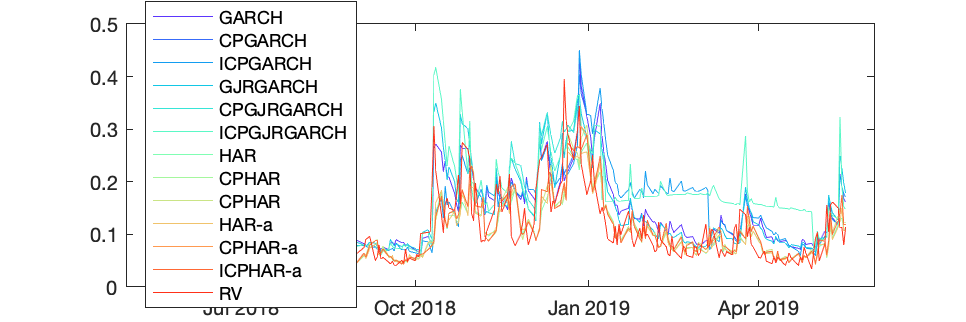

figure;
col=rainbow(13);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(7,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(13,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

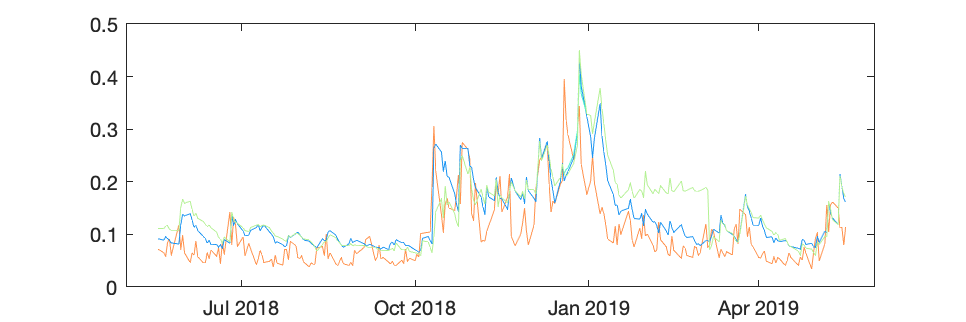

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_garchs.png'])

Volatility forecasts: GJR, CPGJR, CPGJR iteration

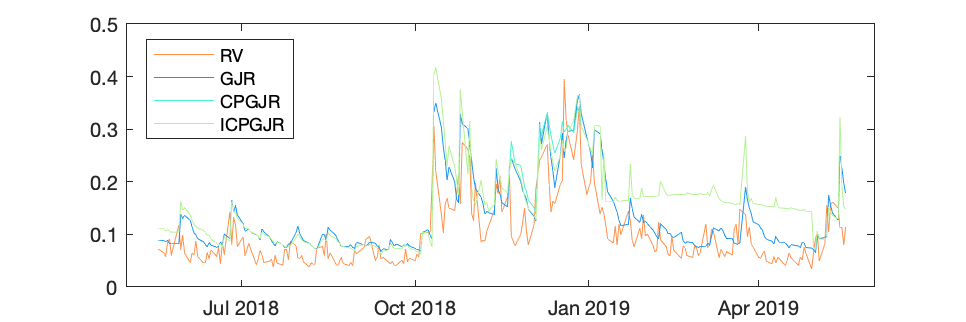


figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_gjrs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

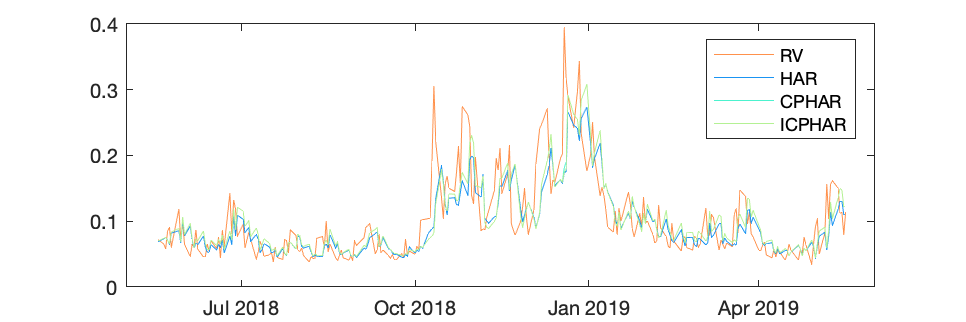

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

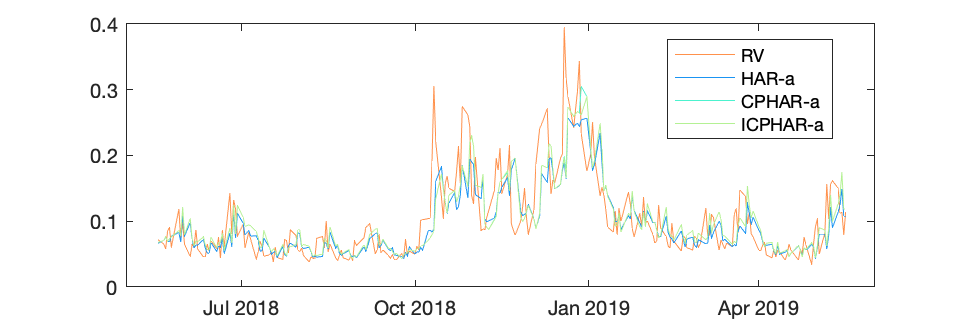

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_haras.png'])

#### Figure of parameters in each estimation window

GARCH

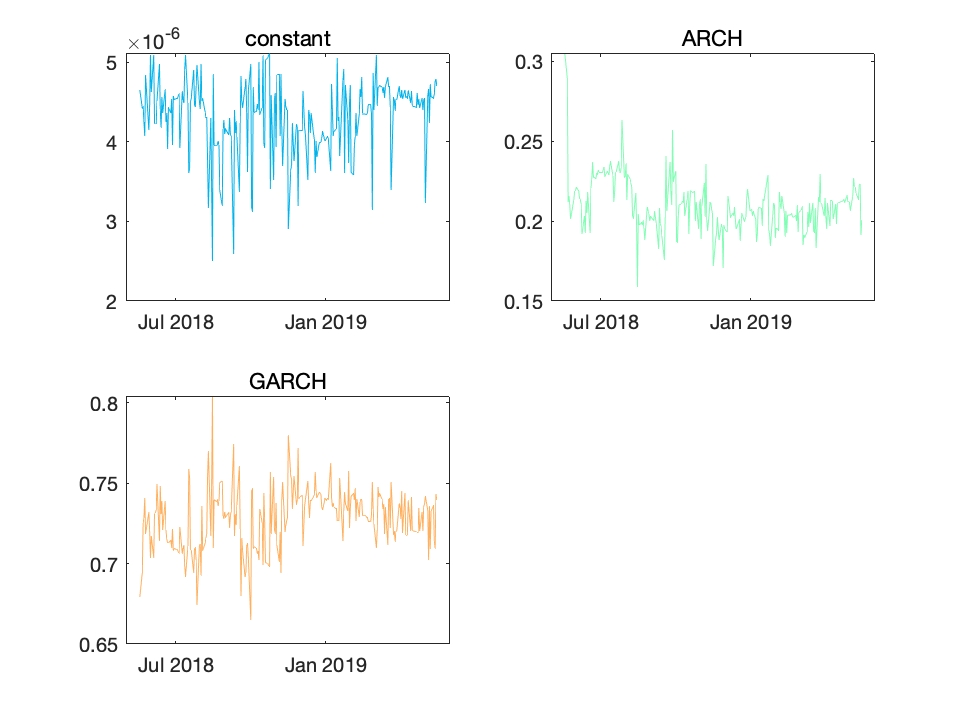

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_garch.png'])

#### Figure of optimal cluster number in each estimation window

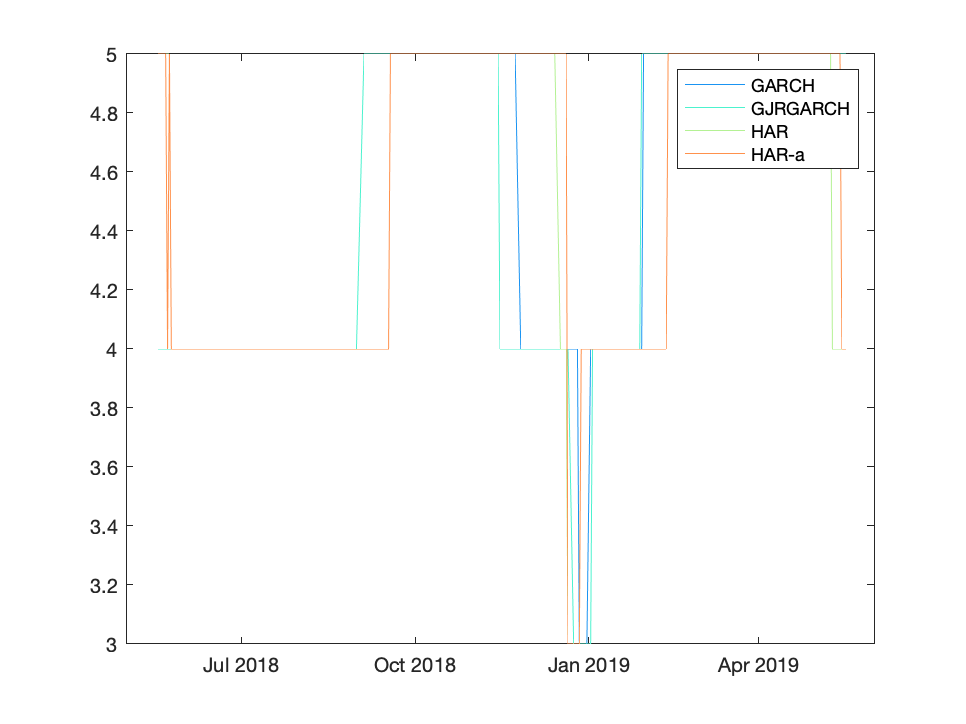

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","HAR","HAR-a")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

Figure of in-sample MAE and MSE

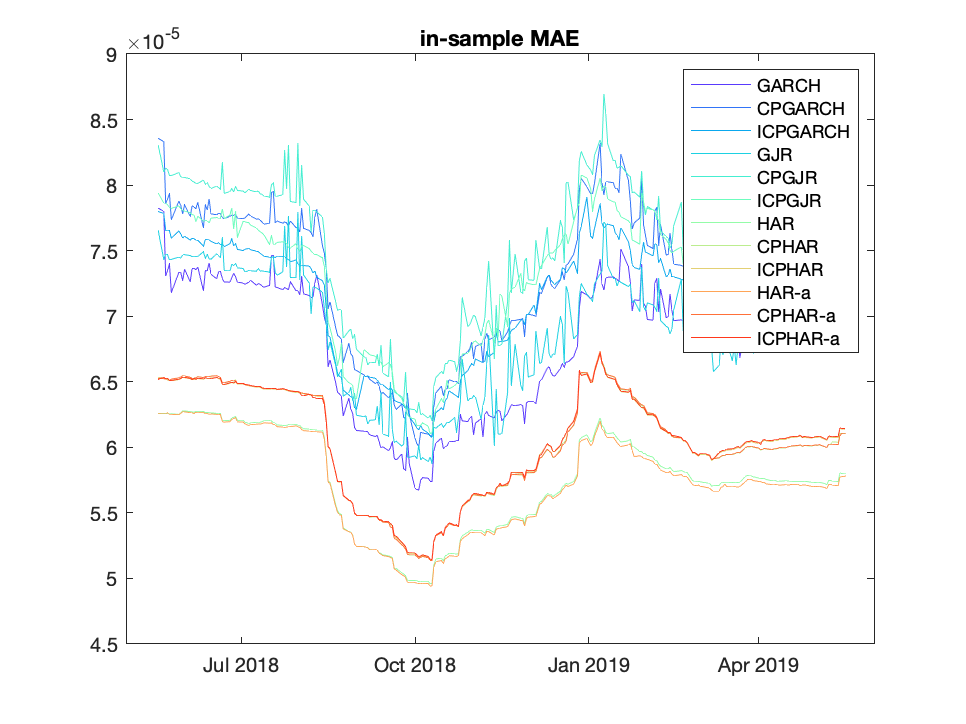

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

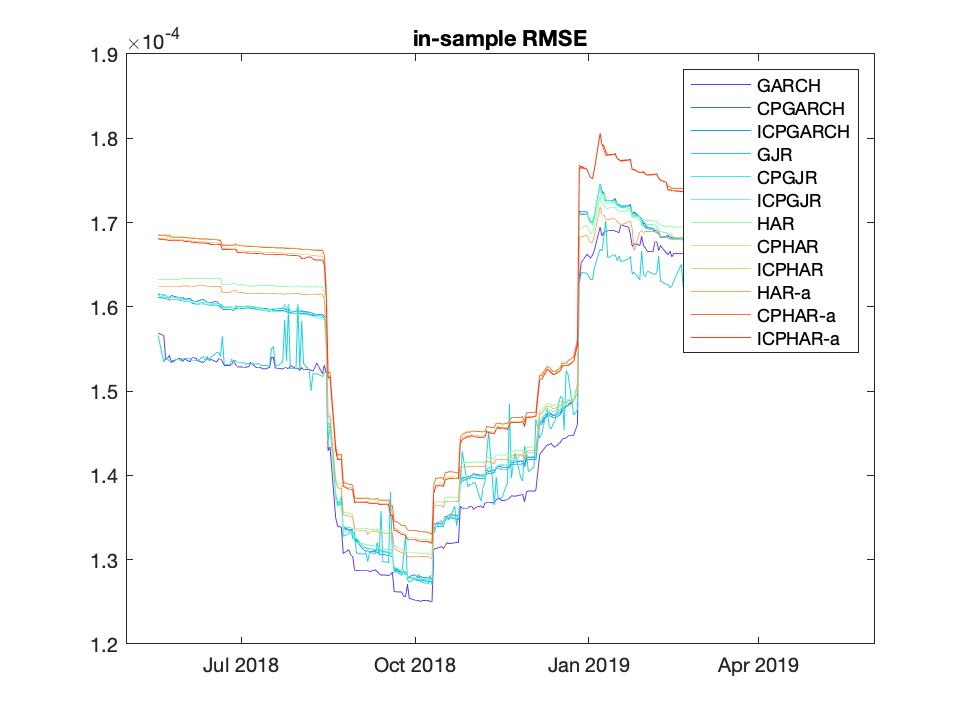

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))%mean(abs(sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)));mean(abs(sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)%mean((sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)).^2);mean((sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 12×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH           0.041681    0.052782
    CPGARCH         0.054317    0.068322
    ICPGARCH        0.054843     0.06901
    GJRGARCH        0.040981    0.052466
    CPGJRGARCH      0.061003    0.074819
    ICPGJRGARCH.    0.059819      0.0734
    HAR             0.028331    0.042573
    CPHAR           0.029628     0.04337
    ICPHAR          0.029697    0.043635
    HAR-a           0.027843    0.041812
    CPHAR-a         0.029099    0.042552
    ICPHAR-a        0.029002    0.042566


ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(12,12);
for i=1:12
    for j=1:12
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 12×1 table
                  dm_test  
                ___________

    GARCH       1×12 double
    CPGARCH     1×12 double
    ICPGARCH    1×12 double
    GJR         1×12 double
    CPGJR       1×12 double
    ICPGJR      1×12 double
    HAR         1×12 double
    CPHAR       1×12 double
    ICPHAR      1×12 double
    HAR-a       1×12 double
    CPHAR-a     1×12 double
    ICPHAR-a    1×12 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 34251.169816 seconds.


## DAX

tic
addpath("Functions/")
Read_Name='DAX_0608.xlsx';
Time_Outsample=[2018,05,18;2019,05,18];
rv=get_rv(Read_Name,Time_Outsample);
Index_Name = 'DAX';
Working_Date = '20240321';
Window_Size = 1000;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: i=64
CPGARCH: i=65
CPGARCH: i=66
CPGARCH: i=67
CPGARCH: i=68
CPGARCH: i=69
CPGARCH: i=70
CPGARCH: i=71
CPGARCH: i=72
C

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);

GJR: i=1
GJR: i=2
GJR: i=3
GJR: i=4
GJR: i=5
GJR: i=6
GJR: i=7
GJR: i=8
GJR: i=9
GJR: i=10
GJR: i=11
GJR: i=12
GJR: i=13
GJR: i=14
GJR: i=15
GJR: i=16
GJR: i=17
GJR: i=18
GJR: i=19
GJR: i=20
GJR: i=21
GJR: i=22
GJR: i=23
GJR: i=24
GJR: i=25
GJR: i=26
GJR: i=27
GJR: i=28
GJR: i=29
GJR: i=30
GJR: i=31
GJR: i=32
GJR: i=33
GJR: i=34
GJR: i=35
GJR: i=36
GJR: i=37
GJR: i=38
GJR: i=39
GJR: i=40
GJR: i=41
GJR: i=42
GJR: i=43
GJR: i=44
GJR: i=45
GJR: i=46
GJR: i=47
GJR: i=48
GJR: i=49
GJR: i=50
GJR: i=51
GJR: i=52
GJR: i=53
GJR: i=54
GJR: i=55
GJR: i=56
GJR: i=57
GJR: i=58
GJR: i=59
GJR: i=60
GJR: i=61
GJR: i=62
GJR: i=63
GJR: i=64
GJR: i=65
GJR: i=66
GJR: i=67
GJR: i=68
GJR: i=69
GJR: i=70
GJR: i=71
GJR: i=72
GJR: i=73
GJR: i=74
GJR: i=75
GJR: i=76
GJR: i=77
GJR: i=78
GJR: i=79
GJR: i=80
GJR: i=81
GJR: i=82
GJR: i=83
GJR: i=84
GJR: i=85
GJR: i=86
GJR: i=87
GJR: i=88
GJR: i=89
GJR: i=90
GJR: i=91
GJR: i=92
GJR: i=93
GJR: i=94
GJR: i=95
GJR: i=96
GJR: i=97
GJR: i=98
GJR: i=99
GJR: i=100
GJR: i=1

results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=1
CPGJR: i=2
CPGJR: i=3
CPGJR: i=4
CPGJR: i=5
CPGJR: i=6
CPGJR: i=7
CPGJR: i=8
CPGJR: i=9
CPGJR: i=10
CPGJR: i=11
CPGJR: i=12
CPGJR: i=13
CPGJR: i=14
CPGJR: i=15
CPGJR: i=16
CPGJR: i=17
CPGJR: i=18
CPGJR: i=19
CPGJR: i=20
CPGJR: i=21
CPGJR: i=22
CPGJR: i=23
CPGJR: i=24
CPGJR: i=25
CPGJR: i=26
CPGJR: i=27
CPGJR: i=28
CPGJR: i=29
CPGJR: i=30
CPGJR: i=31
CPGJR: i=32
CPGJR: i=33
CPGJR: i=34
CPGJR: i=35
CPGJR: i=36
CPGJR: i=37
CPGJR: i=38
CPGJR: i=39
CPGJR: i=40
CPGJR: i=41
CPGJR: i=42
CPGJR: i=43
CPGJR: i=44
CPGJR: i=45
CPGJR: i=46
CPGJR: i=47
CPGJR: i=48
CPGJR: i=49
CPGJR: i=50
CPGJR: i=51
CPGJR: i=52
CPGJR: i=53
CPGJR: i=54
CPGJR: i=55
CPGJR: i=56
CPGJR: i=57
CPGJR: i=58
CPGJR: i=59
CPGJR: i=60
CPGJR: i=61
CPGJR: i=62
CPGJR: i=63
CPGJR: i=64
CPGJR: i=65
CPGJR: i=66
CPGJR: i=67
CPGJR: i=68
CPGJR: i=69
CPGJR: i=70
CPGJR: i=71
CPGJR: i=72
CPGJR: i=73
CPGJR: i=74
CPGJR: i=75
CPGJR: i=76
CPGJR: i=77
CPGJR: i=78
CPGJR: i=79
CPGJR: i=80
CPGJR: i=81
CPGJR: i=82
CPGJR: i=83
CPGJR: i=84
C

results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);

HAR: i=1
HAR: i=2
HAR: i=3
HAR: i=4
HAR: i=5
HAR: i=6
HAR: i=7
HAR: i=8
HAR: i=9
HAR: i=10
HAR: i=11
HAR: i=12
HAR: i=13
HAR: i=14
HAR: i=15
HAR: i=16
HAR: i=17
HAR: i=18
HAR: i=19
HAR: i=20
HAR: i=21
HAR: i=22
HAR: i=23
HAR: i=24
HAR: i=25
HAR: i=26
HAR: i=27
HAR: i=28
HAR: i=29
HAR: i=30
HAR: i=31
HAR: i=32
HAR: i=33
HAR: i=34
HAR: i=35
HAR: i=36
HAR: i=37
HAR: i=38
HAR: i=39
HAR: i=40
HAR: i=41
HAR: i=42
HAR: i=43
HAR: i=44
HAR: i=45
HAR: i=46
HAR: i=47
HAR: i=48
HAR: i=49
HAR: i=50
HAR: i=51
HAR: i=52
HAR: i=53
HAR: i=54
HAR: i=55
HAR: i=56
HAR: i=57
HAR: i=58
HAR: i=59
HAR: i=60
HAR: i=61
HAR: i=62
HAR: i=63
HAR: i=64
HAR: i=65
HAR: i=66
HAR: i=67
HAR: i=68
HAR: i=69
HAR: i=70
HAR: i=71
HAR: i=72
HAR: i=73
HAR: i=74
HAR: i=75
HAR: i=76
HAR: i=77
HAR: i=78
HAR: i=79
HAR: i=80
HAR: i=81
HAR: i=82
HAR: i=83
HAR: i=84
HAR: i=85
HAR: i=86
HAR: i=87
HAR: i=88
HAR: i=89
HAR: i=90
HAR: i=91
HAR: i=92
HAR: i=93
HAR: i=94
HAR: i=95
HAR: i=96
HAR: i=97
HAR: i=98
HAR: i=99
HAR: i=100
HAR: i=1

results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=1
CPHAR: i=2
CPHAR: i=3
CPHAR: i=4
CPHAR: i=5
CPHAR: i=6
CPHAR: i=7
CPHAR: i=8
CPHAR: i=9
CPHAR: i=10
CPHAR: i=11
CPHAR: i=12
CPHAR: i=13
CPHAR: i=14
CPHAR: i=15
CPHAR: i=16
CPHAR: i=17
CPHAR: i=18
CPHAR: i=19
CPHAR: i=20
CPHAR: i=21
CPHAR: i=22
CPHAR: i=23
CPHAR: i=24
CPHAR: i=25
CPHAR: i=26
CPHAR: i=27
CPHAR: i=28
CPHAR: i=29
CPHAR: i=30
CPHAR: i=31
CPHAR: i=32
CPHAR: i=33
CPHAR: i=34
CPHAR: i=35
CPHAR: i=36
CPHAR: i=37
CPHAR: i=38
CPHAR: i=39
CPHAR: i=40
CPHAR: i=41
CPHAR: i=42
CPHAR: i=43
CPHAR: i=44
CPHAR: i=45
CPHAR: i=46
CPHAR: i=47
CPHAR: i=48
CPHAR: i=49
CPHAR: i=50
CPHAR: i=51
CPHAR: i=52
CPHAR: i=53
CPHAR: i=54
CPHAR: i=55
CPHAR: i=56
CPHAR: i=57
CPHAR: i=58
CPHAR: i=59
CPHAR: i=60
CPHAR: i=61
CPHAR: i=62
CPHAR: i=63
CPHAR: i=64
CPHAR: i=65
CPHAR: i=66
CPHAR: i=67
CPHAR: i=68
CPHAR: i=69
CPHAR: i=70
CPHAR: i=71
CPHAR: i=72
CPHAR: i=73
CPHAR: i=74
CPHAR: i=75
CPHAR: i=76
CPHAR: i=77
CPHAR: i=78
CPHAR: i=79
CPHAR: i=80
CPHAR: i=81
CPHAR: i=82
CPHAR: i=83
CPHAR: i=84
C

results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=1
ICPHAR: i=2
ICPHAR: i=3
ICPHAR: i=4
ICPHAR: i=5
ICPHAR: i=6
ICPHAR: i=7
ICPHAR: i=8
ICPHAR: i=9
ICPHAR: i=10
ICPHAR: i=11
ICPHAR: i=12
ICPHAR: i=13
ICPHAR: i=14
ICPHAR: i=15
ICPHAR: i=16
ICPHAR: i=17
ICPHAR: i=18
ICPHAR: i=19
ICPHAR: i=20
ICPHAR: i=21
ICPHAR: i=22
ICPHAR: i=23
ICPHAR: i=24
ICPHAR: i=25
ICPHAR: i=26
ICPHAR: i=27
ICPHAR: i=28
ICPHAR: i=29
ICPHAR: i=30
ICPHAR: i=31
ICPHAR: i=32
ICPHAR: i=33
ICPHAR: i=34
ICPHAR: i=35
ICPHAR: i=36
ICPHAR: i=37
ICPHAR: i=38
ICPHAR: i=39
ICPHAR: i=40
ICPHAR: i=41
ICPHAR: i=42
ICPHAR: i=43
ICPHAR: i=44
ICPHAR: i=45
ICPHAR: i=46
ICPHAR: i=47
ICPHAR: i=48
ICPHAR: i=49
ICPHAR: i=50
ICPHAR: i=51
ICPHAR: i=52
ICPHAR: i=53
ICPHAR: i=54
ICPHAR: i=55
ICPHAR: i=56
ICPHAR: i=57
ICPHAR: i=58
ICPHAR: i=59
ICPHAR: i=60
ICPHAR: i=61
ICPHAR: i=62
ICPHAR: i=63
ICPHAR: i=64
ICPHAR: i=65
ICPHAR: i=66
ICPHAR: i=67
ICPHAR: i=68
ICPHAR: i=69
ICPHAR: i=70
ICPHAR: i=71
ICPHAR: i=72
ICPHAR: i=73
ICPHAR: i=74
ICPHAR: i=75
ICPHAR: i=76
ICPHAR: i=77
ICPHAR: 

results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);

HAR-a: i=2
HAR-a: i=3
HAR-a: i=4
HAR-a: i=5
HAR-a: i=6
HAR-a: i=7
HAR-a: i=8
HAR-a: i=9
HAR-a: i=10
HAR-a: i=11
HAR-a: i=12
HAR-a: i=13
HAR-a: i=14
HAR-a: i=15
HAR-a: i=16
HAR-a: i=17
HAR-a: i=18
HAR-a: i=19
HAR-a: i=20
HAR-a: i=21
HAR-a: i=22
HAR-a: i=23
HAR-a: i=24
HAR-a: i=25
HAR-a: i=26
HAR-a: i=27
HAR-a: i=28
HAR-a: i=29
HAR-a: i=30
HAR-a: i=31
HAR-a: i=32
HAR-a: i=33
HAR-a: i=34
HAR-a: i=35
HAR-a: i=36
HAR-a: i=37
HAR-a: i=38
HAR-a: i=39
HAR-a: i=40
HAR-a: i=41
HAR-a: i=42
HAR-a: i=43
HAR-a: i=44
HAR-a: i=45
HAR-a: i=46
HAR-a: i=47
HAR-a: i=48
HAR-a: i=49
HAR-a: i=50
HAR-a: i=51
HAR-a: i=52
HAR-a: i=53
HAR-a: i=54
HAR-a: i=55
HAR-a: i=56
HAR-a: i=57
HAR-a: i=58
HAR-a: i=59
HAR-a: i=60
HAR-a: i=61
HAR-a: i=62
HAR-a: i=63
HAR-a: i=64
HAR-a: i=65
HAR-a: i=66
HAR-a: i=67
HAR-a: i=68
HAR-a: i=69
HAR-a: i=70
HAR-a: i=71
HAR-a: i=72
HAR-a: i=73
HAR-a: i=74
HAR-a: i=75
HAR-a: i=76
HAR-a: i=77
HAR-a: i=78
HAR-a: i=79
HAR-a: i=80
HAR-a: i=81
HAR-a: i=82
HAR-a: i=83
HAR-a: i=84
HAR-a: i=85


results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=1
CPHAR-a: i=2
CPHAR-a: i=3
CPHAR-a: i=4
CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
C

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=12
ICPHAR-a: i=13
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=32
ICPHAR-a: i=33
ICPHAR-a: i=34
ICPHAR-a: i=35
ICPHAR-a: i=36
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPH

#### Save forecast volatility

Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ...
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:12
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.ismae_GARCH,results_CPGARCH.ismae_CPGARCH,results_ICPGARCH.ismae_ICPGARCH, ...
    results_GJR.ismae_GJR,results_CPGJR.ismae_CPGJR,results_ICPGJR.ismae_ICPGJR, ... 
    results_HAR.ismae_HAR,results_CPHAR.ismae_CPHAR,results_ICPHAR.ismae_ICPHAR, ...
    results_HAR_a.ismae_HAR_a,results_CPHAR_a.ismae_CPHAR_a,results_ICPHAR_a.ismae_ICPHAR_a, ...
    'VariableNames',{'Date','ismae_GARCH','ismae_CPGARCH','ismae_ICPGARCH', ...
    'ismae_GJR','ismae_CPGJR','ismae_ICPGJR', ...
    'ismae_HAR','ismae_CPHAR','ismae_ICPHAR', ...
    'ismae_HAR_a','ismae_CPHAR_a','ismae_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_MAE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.isrmse_GARCH,results_CPGARCH.isrmse_CPGARCH,results_ICPGARCH.isrmse_ICPGARCH, ...
    results_GJR.isrmse_GJR,results_CPGJR.isrmse_CPGJR,results_ICPGJR.isrmse_ICPGJR, ... 
    results_HAR.isrmse_HAR,results_CPHAR.isrmse_CPHAR,results_ICPHAR.isrmse_ICPHAR, ...
    results_HAR_a.isrmse_HAR_a,results_CPHAR_a.isrmse_CPHAR_a,results_ICPHAR_a.isrmse_ICPHAR_a, ...
    'VariableNames',{'Date','isrmse_GARCH','isrmse_CPGARCH','isrmse_ICPGARCH', ...
    'isrmse_GJR','isrmse_CPGJR','isrmse_ICPGJR', ...
    'isrmse_HAR','isrmse_CPHAR','isrmse_ICPHAR', ...
    'isrmse_HAR_a','isrmse_CPHAR_a','isrmse_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_RMSE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_CPGARCH.K, ...
    results_CPGJR.K, ... 
    results_CPHAR.K, ...
    results_CPHAR_a.isrmse_CPHAR_a, ...
    'VariableNames',{'Date','K_CPGARCH',...
    'K_CPGJR',...
    'K_CPHAR',...
    'K_CPHAR_a'});
writetable(Output_Table,[results_folder,'/','K_',Working_Date,'.xlsx']);

#### Load forecast volatility

for i=1:12
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

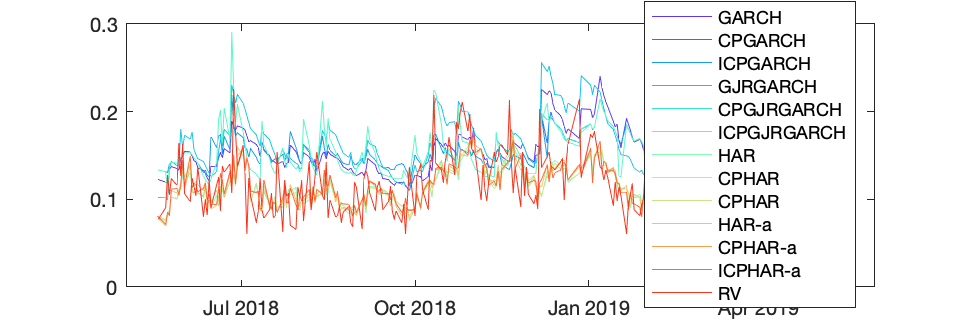

figure;
col=rainbow(13);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(7,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(13,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

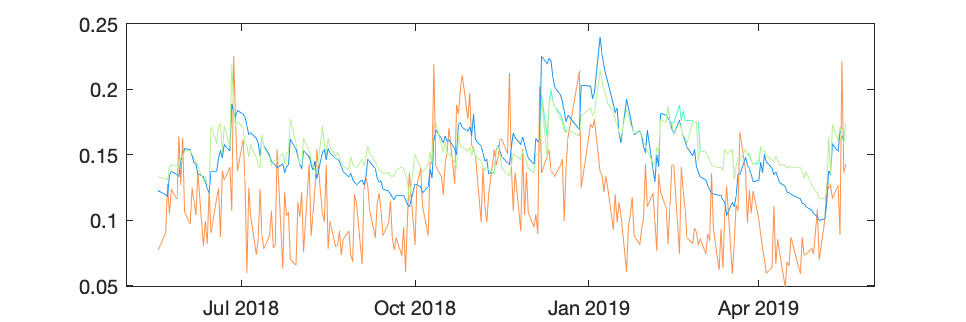

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
% legend("RV","GARCH","CPGARCH","CPGARCH Ite.");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'garchs.png'])

Volatility forecasts: GJR, CPGJR, CPGJR iteration

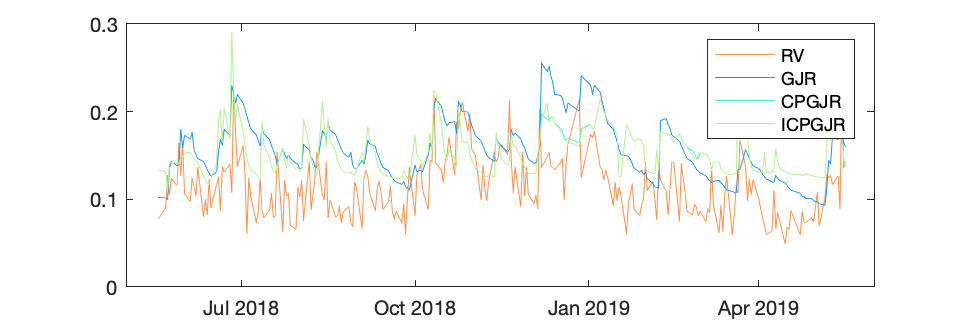

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'gjrs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

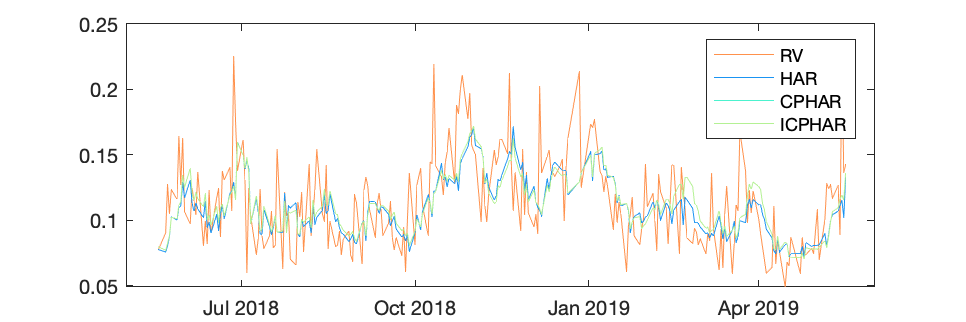

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

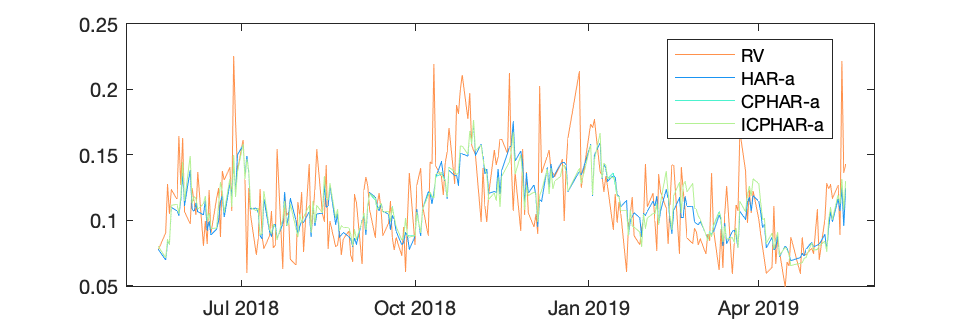

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'haras.png'])

#### Figure of parameters in each estimation window

GARCH

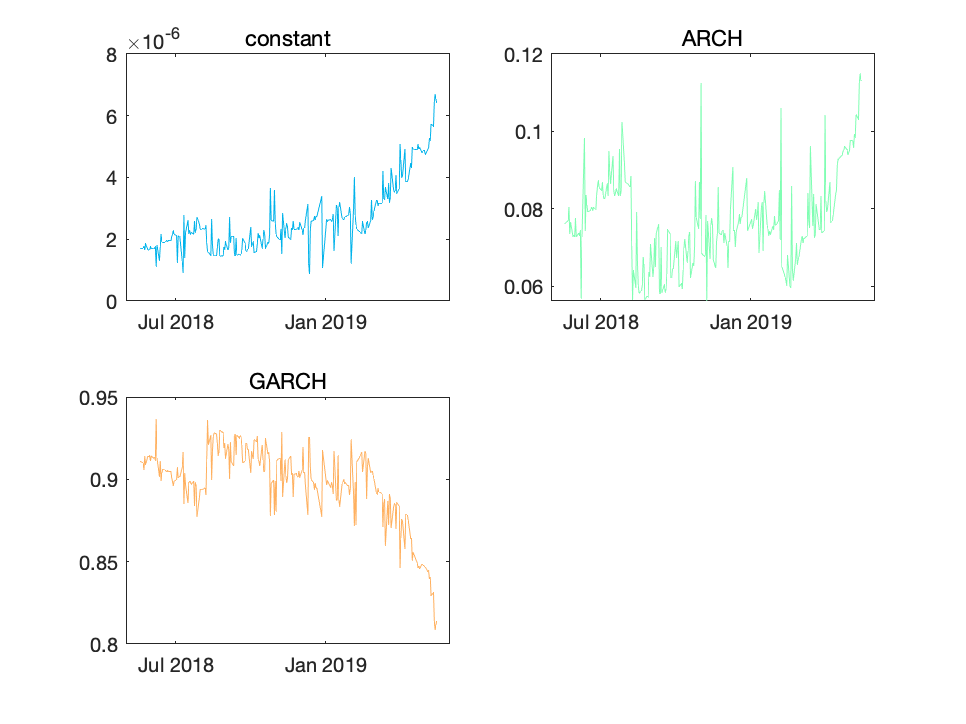

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_',Index_Name,'garch.png'])

#### Figure of optimal cluster number in each estimation window

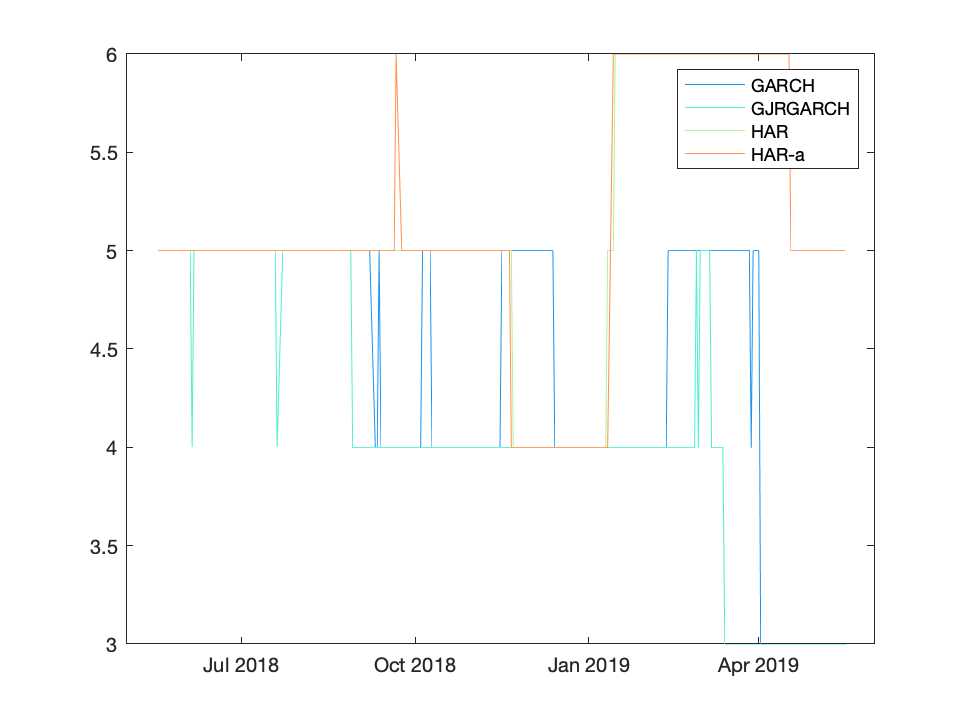

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","HAR","HAR-a")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

#### Figure of in-sample MAE and MSE

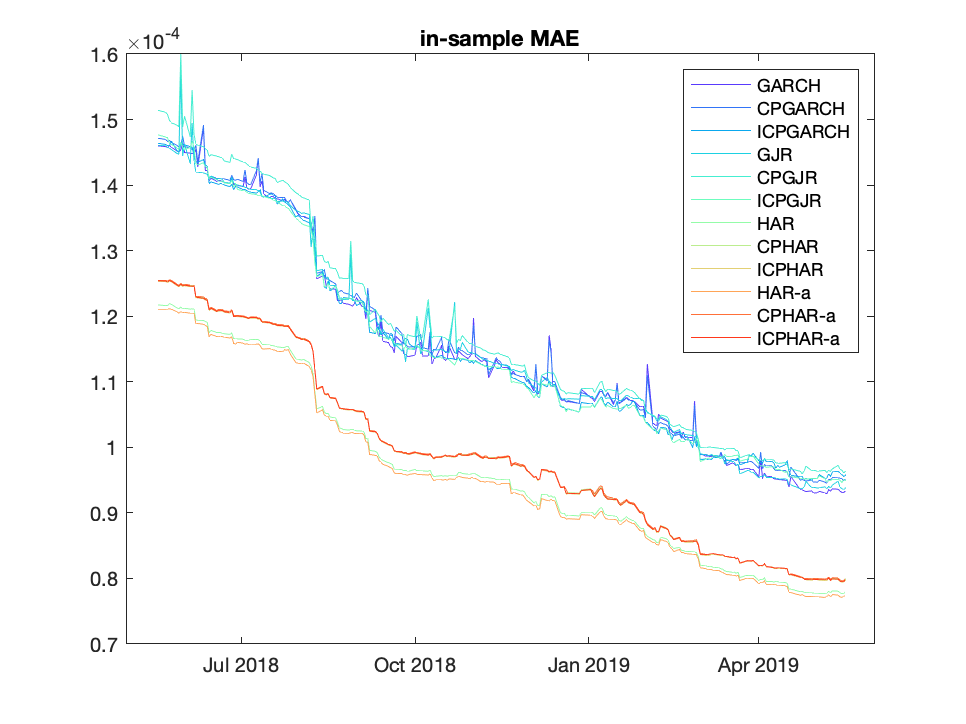

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

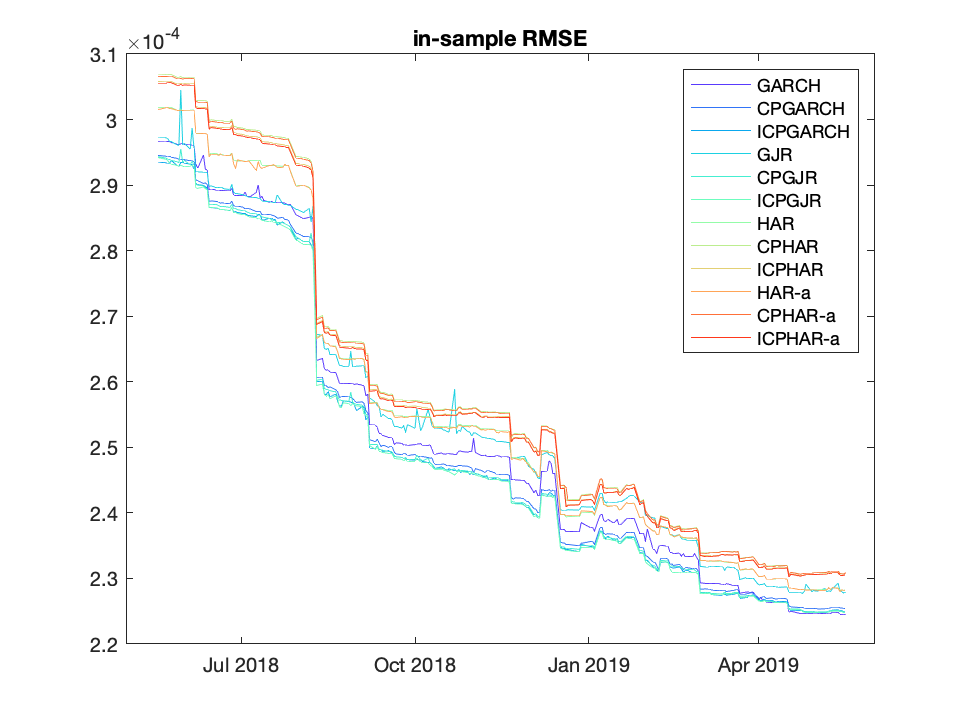

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

#### MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 12×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH           0.041639    0.049173
    CPGARCH         0.045655    0.052949
    ICPGARCH        0.045111    0.052316
    GJRGARCH        0.045255    0.053014
    CPGJRGARCH      0.044455     0.05287
    ICPGJRGARCH.    0.044396    0.052829
    HAR              0.02276    0.029552
    CPHAR           0.023344    0.029716
    ICPHAR          0.023344    0.029716
    HAR-a           0.022058    0.028992
    CPHAR-a         0.022348    0.028939
    ICPHAR-a        0.022323    0.028898


ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

#### DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(12,12);
for i=1:12
    for j=1:12
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 12×1 table
                  dm_test  
                ___________

    GARCH       1×12 double
    CPGARCH     1×12 double
    ICPGARCH    1×12 double
    GJR         1×12 double
    CPGJR       1×12 double
    ICPGJR      1×12 double
    HAR         1×12 double
    CPHAR       1×12 double
    ICPHAR      1×12 double
    HAR-a       1×12 double
    CPHAR-a     1×12 double
    ICPHAR-a    1×12 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 33045.516687 seconds.


### FTSE

tic
addpath("Functions/")
Read_Name='FTSE_0608.xlsx';
Time_Outsample=[2018,05,18;2019,05,18];
rv=get_rv(Read_Name,Time_Outsample);
Index_Name = 'FTSE';
Working_Date = '20240321';
Window_Size = 1000;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: i=64
CPGARCH: i=65
CPGARCH: i=66
CPGARCH: i=67
CPGARCH: i=68
CPGARCH: i=69
CPGARCH: i=70
CPGARCH: i=71
CPGARCH: i=72
C

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);

GJR: i=1
GJR: i=2
GJR: i=3
GJR: i=4
GJR: i=5
GJR: i=6
GJR: i=7
GJR: i=8
GJR: i=9
GJR: i=10
GJR: i=11
GJR: i=12
GJR: i=13
GJR: i=14
GJR: i=15
GJR: i=16
GJR: i=17
GJR: i=18
GJR: i=19
GJR: i=20
GJR: i=21
GJR: i=22
GJR: i=23
GJR: i=24
GJR: i=25
GJR: i=26
GJR: i=27
GJR: i=28
GJR: i=29
GJR: i=30
GJR: i=31
GJR: i=32
GJR: i=33
GJR: i=34
GJR: i=35
GJR: i=36
GJR: i=37
GJR: i=38
GJR: i=39
GJR: i=40
GJR: i=41
GJR: i=42
GJR: i=43
GJR: i=44
GJR: i=45
GJR: i=46
GJR: i=47
GJR: i=48
GJR: i=49
GJR: i=50
GJR: i=51
GJR: i=52
GJR: i=53
GJR: i=54
GJR: i=55
GJR: i=56
GJR: i=57
GJR: i=58
GJR: i=59
GJR: i=60
GJR: i=61
GJR: i=62
GJR: i=63
GJR: i=64
GJR: i=65
GJR: i=66
GJR: i=67
GJR: i=68
GJR: i=69
GJR: i=70
GJR: i=71
GJR: i=72
GJR: i=73
GJR: i=74
GJR: i=75
GJR: i=76
GJR: i=77
GJR: i=78
GJR: i=79
GJR: i=80
GJR: i=81
GJR: i=82
GJR: i=83
GJR: i=84
GJR: i=85
GJR: i=86
GJR: i=87
GJR: i=88
GJR: i=89
GJR: i=90
GJR: i=91
GJR: i=92
GJR: i=93
GJR: i=94
GJR: i=95
GJR: i=96
GJR: i=97
GJR: i=98
GJR: i=99
GJR: i=100
GJR: i=1

results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=1
CPGJR: i=2
CPGJR: i=3
CPGJR: i=4
CPGJR: i=5
CPGJR: i=6
CPGJR: i=7
CPGJR: i=8
CPGJR: i=9
CPGJR: i=10
CPGJR: i=11
CPGJR: i=12
CPGJR: i=13
CPGJR: i=14
CPGJR: i=15
CPGJR: i=16
CPGJR: i=17
CPGJR: i=18
CPGJR: i=19
CPGJR: i=20
CPGJR: i=21
CPGJR: i=22
CPGJR: i=23
CPGJR: i=24
CPGJR: i=25
CPGJR: i=26
CPGJR: i=27
CPGJR: i=28
CPGJR: i=29
CPGJR: i=30
CPGJR: i=31
CPGJR: i=32
CPGJR: i=33
CPGJR: i=34
CPGJR: i=35
CPGJR: i=36
CPGJR: i=37
CPGJR: i=38
CPGJR: i=39
CPGJR: i=40
CPGJR: i=41
CPGJR: i=42
CPGJR: i=43
CPGJR: i=44
CPGJR: i=45
CPGJR: i=46
CPGJR: i=47
CPGJR: i=48
CPGJR: i=49
CPGJR: i=50
CPGJR: i=51
CPGJR: i=52
CPGJR: i=53
CPGJR: i=54
CPGJR: i=55
CPGJR: i=56
CPGJR: i=57
CPGJR: i=58
CPGJR: i=59
CPGJR: i=60
CPGJR: i=61
CPGJR: i=62
CPGJR: i=63
CPGJR: i=64
CPGJR: i=65
CPGJR: i=66
CPGJR: i=67
CPGJR: i=68
CPGJR: i=69
CPGJR: i=70
CPGJR: i=71
CPGJR: i=72
CPGJR: i=73
CPGJR: i=74
CPGJR: i=75
CPGJR: i=76
CPGJR: i=77
CPGJR: i=78
CPGJR: i=79
CPGJR: i=80
CPGJR: i=81
CPGJR: i=82
CPGJR: i=83
CPGJR: i=84
C

results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);

HAR: i=1
HAR: i=2
HAR: i=3
HAR: i=4
HAR: i=5
HAR: i=6
HAR: i=7
HAR: i=8
HAR: i=9
HAR: i=10
HAR: i=11
HAR: i=12
HAR: i=13
HAR: i=14
HAR: i=15
HAR: i=16
HAR: i=17
HAR: i=18
HAR: i=19
HAR: i=20
HAR: i=21
HAR: i=22
HAR: i=23
HAR: i=24
HAR: i=25
HAR: i=26
HAR: i=27
HAR: i=28
HAR: i=29
HAR: i=30
HAR: i=31
HAR: i=32
HAR: i=33
HAR: i=34
HAR: i=35
HAR: i=36
HAR: i=37
HAR: i=38
HAR: i=39
HAR: i=40
HAR: i=41
HAR: i=42
HAR: i=43
HAR: i=44
HAR: i=45
HAR: i=46
HAR: i=47
HAR: i=48
HAR: i=49
HAR: i=50
HAR: i=51
HAR: i=52
HAR: i=53
HAR: i=54
HAR: i=55
HAR: i=56
HAR: i=57
HAR: i=58
HAR: i=59
HAR: i=60
HAR: i=61
HAR: i=62
HAR: i=63
HAR: i=64
HAR: i=65
HAR: i=66
HAR: i=67
HAR: i=68
HAR: i=69
HAR: i=70
HAR: i=71
HAR: i=72
HAR: i=73
HAR: i=74
HAR: i=75
HAR: i=76
HAR: i=77
HAR: i=78
HAR: i=79
HAR: i=80
HAR: i=81
HAR: i=82
HAR: i=83
HAR: i=84
HAR: i=85
HAR: i=86
HAR: i=87
HAR: i=88
HAR: i=89
HAR: i=90
HAR: i=91
HAR: i=92
HAR: i=93
HAR: i=94
HAR: i=95
HAR: i=96
HAR: i=97
HAR: i=98
HAR: i=99
HAR: i=100
HAR: i=1

results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=1
CPHAR: i=2
CPHAR: i=3
CPHAR: i=4
CPHAR: i=5
CPHAR: i=6
CPHAR: i=7
CPHAR: i=8
CPHAR: i=9
CPHAR: i=10
CPHAR: i=11
CPHAR: i=12
CPHAR: i=13
CPHAR: i=14
CPHAR: i=15
CPHAR: i=16
CPHAR: i=17
CPHAR: i=18
CPHAR: i=19
CPHAR: i=20
CPHAR: i=21
CPHAR: i=22
CPHAR: i=23
CPHAR: i=24
CPHAR: i=25
CPHAR: i=26
CPHAR: i=27
CPHAR: i=28
CPHAR: i=29
CPHAR: i=30
CPHAR: i=31
CPHAR: i=32
CPHAR: i=33
CPHAR: i=34
CPHAR: i=35
CPHAR: i=36
CPHAR: i=37
CPHAR: i=38
CPHAR: i=39
CPHAR: i=40
CPHAR: i=41
CPHAR: i=42
CPHAR: i=43
CPHAR: i=44
CPHAR: i=45
CPHAR: i=46
CPHAR: i=47
CPHAR: i=48
CPHAR: i=49
CPHAR: i=50
CPHAR: i=51
CPHAR: i=52
CPHAR: i=53
CPHAR: i=54
CPHAR: i=55
CPHAR: i=56
CPHAR: i=57
CPHAR: i=58
CPHAR: i=59
CPHAR: i=60
CPHAR: i=61
CPHAR: i=62
CPHAR: i=63
CPHAR: i=64
CPHAR: i=65
CPHAR: i=66
CPHAR: i=67
CPHAR: i=68
CPHAR: i=69
CPHAR: i=70
CPHAR: i=71
CPHAR: i=72
CPHAR: i=73
CPHAR: i=74
CPHAR: i=75
CPHAR: i=76
CPHAR: i=77
CPHAR: i=78
CPHAR: i=79
CPHAR: i=80
CPHAR: i=81
CPHAR: i=82
CPHAR: i=83
CPHAR: i=84
C

results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=1
ICPHAR: i=2
ICPHAR: i=3
ICPHAR: i=4
ICPHAR: i=5
ICPHAR: i=6
ICPHAR: i=7
ICPHAR: i=8
ICPHAR: i=9
ICPHAR: i=10
ICPHAR: i=11
ICPHAR: i=12
ICPHAR: i=13
ICPHAR: i=14
ICPHAR: i=15
ICPHAR: i=16
ICPHAR: i=17
ICPHAR: i=18
ICPHAR: i=19
ICPHAR: i=20
ICPHAR: i=21
ICPHAR: i=22
ICPHAR: i=23
ICPHAR: i=24
ICPHAR: i=25
ICPHAR: i=26
ICPHAR: i=27
ICPHAR: i=28
ICPHAR: i=29
ICPHAR: i=30
ICPHAR: i=31
ICPHAR: i=32
ICPHAR: i=33
ICPHAR: i=34
ICPHAR: i=35
ICPHAR: i=36
ICPHAR: i=37
ICPHAR: i=38
ICPHAR: i=39
ICPHAR: i=40
ICPHAR: i=41
ICPHAR: i=42
ICPHAR: i=43
ICPHAR: i=44
ICPHAR: i=45
ICPHAR: i=46
ICPHAR: i=47
ICPHAR: i=48
ICPHAR: i=49
ICPHAR: i=50
ICPHAR: i=51
ICPHAR: i=52
ICPHAR: i=53
ICPHAR: i=54
ICPHAR: i=55
ICPHAR: i=56
ICPHAR: i=57
ICPHAR: i=58
ICPHAR: i=59
ICPHAR: i=60
ICPHAR: i=61
ICPHAR: i=62
ICPHAR: i=63
ICPHAR: i=64
ICPHAR: i=65
ICPHAR: i=66
ICPHAR: i=67
ICPHAR: i=68
ICPHAR: i=69
ICPHAR: i=70
ICPHAR: i=71
ICPHAR: i=72
ICPHAR: i=73
ICPHAR: i=74
ICPHAR: i=75
ICPHAR: i=76
ICPHAR: i=77
ICPHAR: 

results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);

HAR-a: i=1
HAR-a: i=2
HAR-a: i=3
HAR-a: i=4
HAR-a: i=5
HAR-a: i=6
HAR-a: i=7
HAR-a: i=8
HAR-a: i=9
HAR-a: i=10
HAR-a: i=11
HAR-a: i=12
HAR-a: i=13
HAR-a: i=14
HAR-a: i=15
HAR-a: i=16
HAR-a: i=17
HAR-a: i=18
HAR-a: i=19
HAR-a: i=20
HAR-a: i=21
HAR-a: i=22
HAR-a: i=23
HAR-a: i=24
HAR-a: i=25
HAR-a: i=26
HAR-a: i=27
HAR-a: i=28
HAR-a: i=29
HAR-a: i=30
HAR-a: i=31
HAR-a: i=32
HAR-a: i=33
HAR-a: i=34
HAR-a: i=35
HAR-a: i=36
HAR-a: i=37
HAR-a: i=38
HAR-a: i=39
HAR-a: i=40
HAR-a: i=41
HAR-a: i=42
HAR-a: i=43
HAR-a: i=44
HAR-a: i=45
HAR-a: i=46
HAR-a: i=47
HAR-a: i=48
HAR-a: i=49
HAR-a: i=50
HAR-a: i=51
HAR-a: i=52
HAR-a: i=53
HAR-a: i=54
HAR-a: i=55
HAR-a: i=56
HAR-a: i=57
HAR-a: i=58
HAR-a: i=59
HAR-a: i=60
HAR-a: i=61
HAR-a: i=62
HAR-a: i=63
HAR-a: i=64
HAR-a: i=65
HAR-a: i=66
HAR-a: i=67
HAR-a: i=68
HAR-a: i=69
HAR-a: i=70
HAR-a: i=71
HAR-a: i=72
HAR-a: i=73
HAR-a: i=74
HAR-a: i=75
HAR-a: i=76
HAR-a: i=77
HAR-a: i=78
HAR-a: i=79
HAR-a: i=80
HAR-a: i=81
HAR-a: i=82
HAR-a: i=83
HAR-a: i=84
H

results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=1
CPHAR-a: i=2
CPHAR-a: i=3
CPHAR-a: i=4
CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
C

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=12
ICPHAR-a: i=13
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=32
ICPHAR-a: i=33
ICPHAR-a: i=34
ICPHAR-a: i=35
ICPHAR-a: i=36
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPH

Save forecast volatility

Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ...
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:12
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.ismae_GARCH,results_CPGARCH.ismae_CPGARCH,results_ICPGARCH.ismae_ICPGARCH, ...
    results_GJR.ismae_GJR,results_CPGJR.ismae_CPGJR,results_ICPGJR.ismae_ICPGJR, ... 
    results_HAR.ismae_HAR,results_CPHAR.ismae_CPHAR,results_ICPHAR.ismae_ICPHAR, ...
    results_HAR_a.ismae_HAR_a,results_CPHAR_a.ismae_CPHAR_a,results_ICPHAR_a.ismae_ICPHAR_a, ...
    'VariableNames',{'Date','ismae_GARCH','ismae_CPGARCH','ismae_ICPGARCH', ...
    'ismae_GJR','ismae_CPGJR','ismae_ICPGJR', ...
    'ismae_HAR','ismae_CPHAR','ismae_ICPHAR', ...
    'ismae_HAR_a','ismae_CPHAR_a','ismae_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_MAE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_GARCH.isrmse_GARCH,results_CPGARCH.isrmse_CPGARCH,results_ICPGARCH.isrmse_ICPGARCH, ...
    results_GJR.isrmse_GJR,results_CPGJR.isrmse_CPGJR,results_ICPGJR.isrmse_ICPGJR, ... 
    results_HAR.isrmse_HAR,results_CPHAR.isrmse_CPHAR,results_ICPHAR.isrmse_ICPHAR, ...
    results_HAR_a.isrmse_HAR_a,results_CPHAR_a.isrmse_CPHAR_a,results_ICPHAR_a.isrmse_ICPHAR_a, ...
    'VariableNames',{'Date','isrmse_GARCH','isrmse_CPGARCH','isrmse_ICPGARCH', ...
    'isrmse_GJR','isrmse_CPGJR','isrmse_ICPGJR', ...
    'isrmse_HAR','isrmse_CPHAR','isrmse_ICPHAR', ...
    'isrmse_HAR_a','isrmse_CPHAR_a','isrmse_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Insample_RMSE_',Working_Date,'.xlsx']);
Output_Table=table(Timeline_outsample,results_CPGARCH.K, ...
    results_CPGJR.K, ... 
    results_CPHAR.K, ...
    results_CPHAR_a.isrmse_CPHAR_a, ...
    'VariableNames',{'Date','K_CPGARCH',...
    'K_CPGJR',...
    'K_CPHAR',...
    'K_CPHAR_a'});
writetable(Output_Table,[results_folder,'/','K_',Working_Date,'.xlsx']);

Load forecast volatility

for i=1:12
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

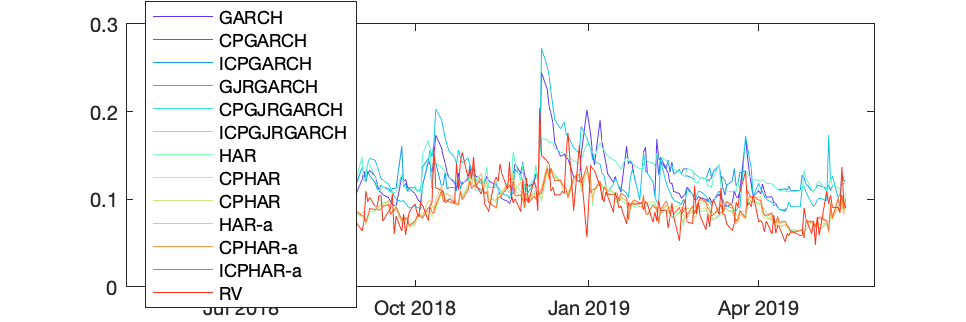

figure;
col=rainbow(13);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(7,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(13,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

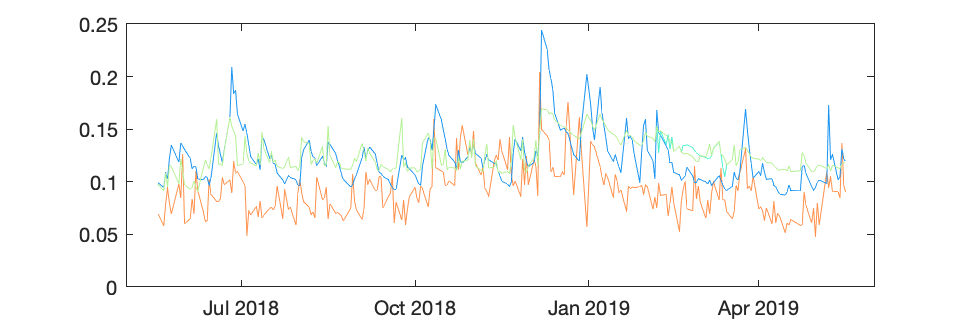

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
% legend("RV","GARCH","CPGARCH","CPGARCH Ite.");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'garchs.png'])

Volatility forecasts: GJR, CPGJR, CPGJR iteration

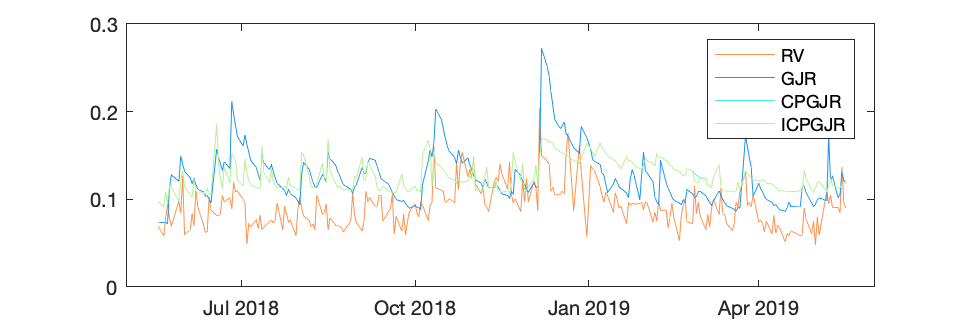

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'gjrs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

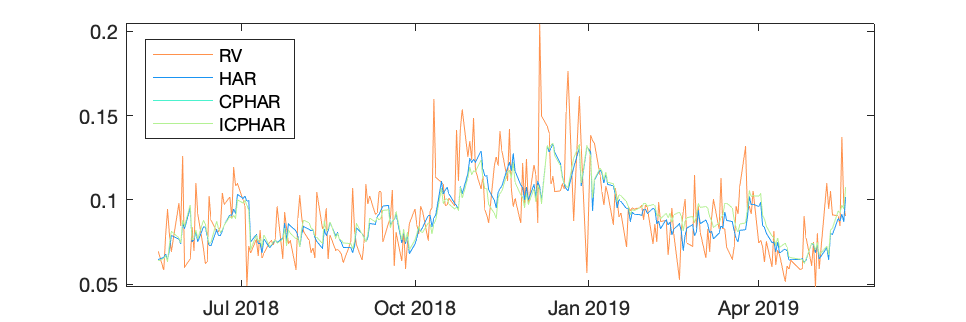

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

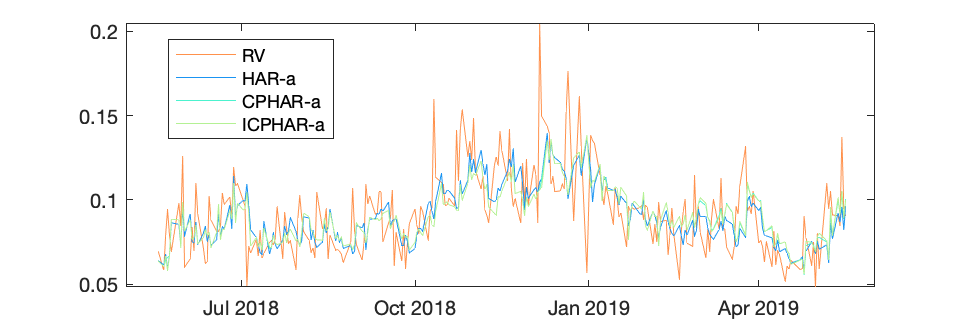

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'haras.png'])

#### Figure of parameters in each estimation window

GARCH

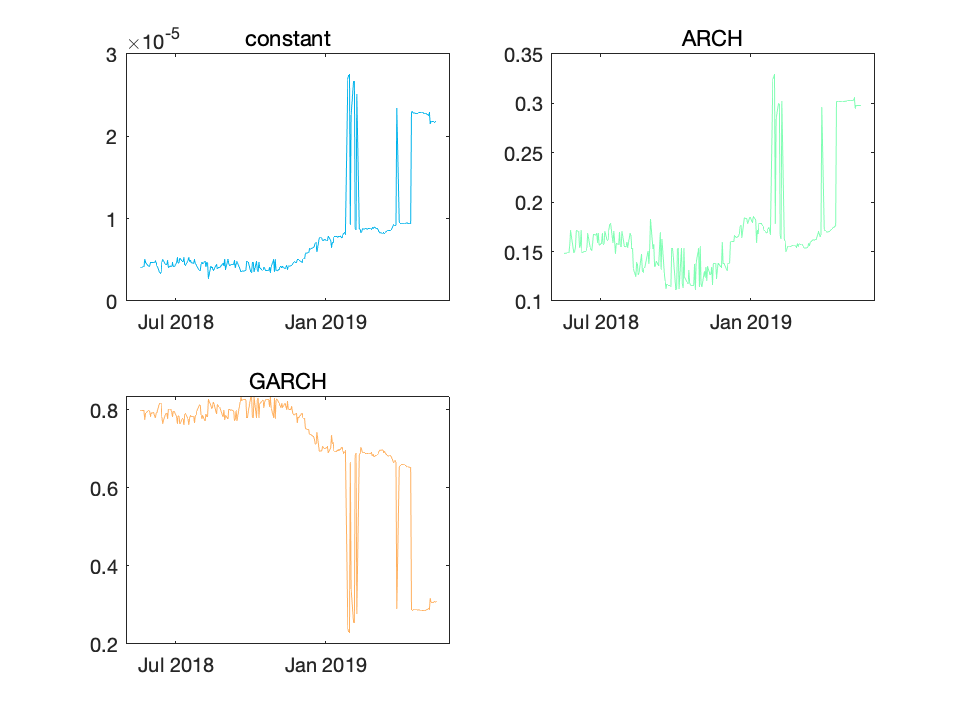

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_',Index_Name,'garch.png'])

#### Figure of optimal cluster number in each estimation window

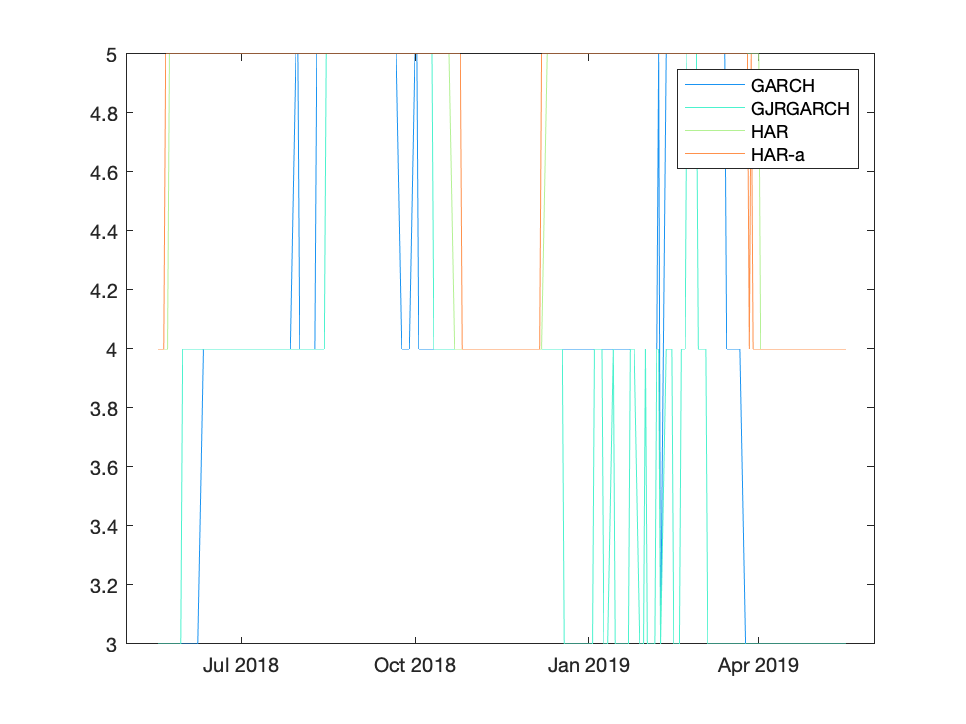

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","HAR","HAR-a")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

#### Figure of in-sample MAE and MSE

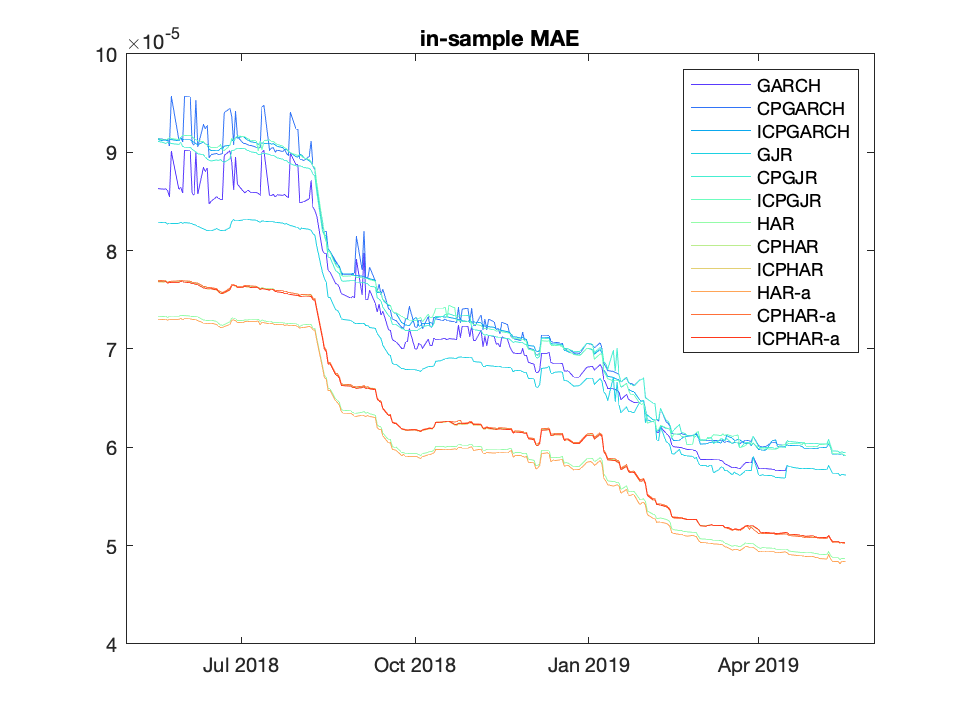

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

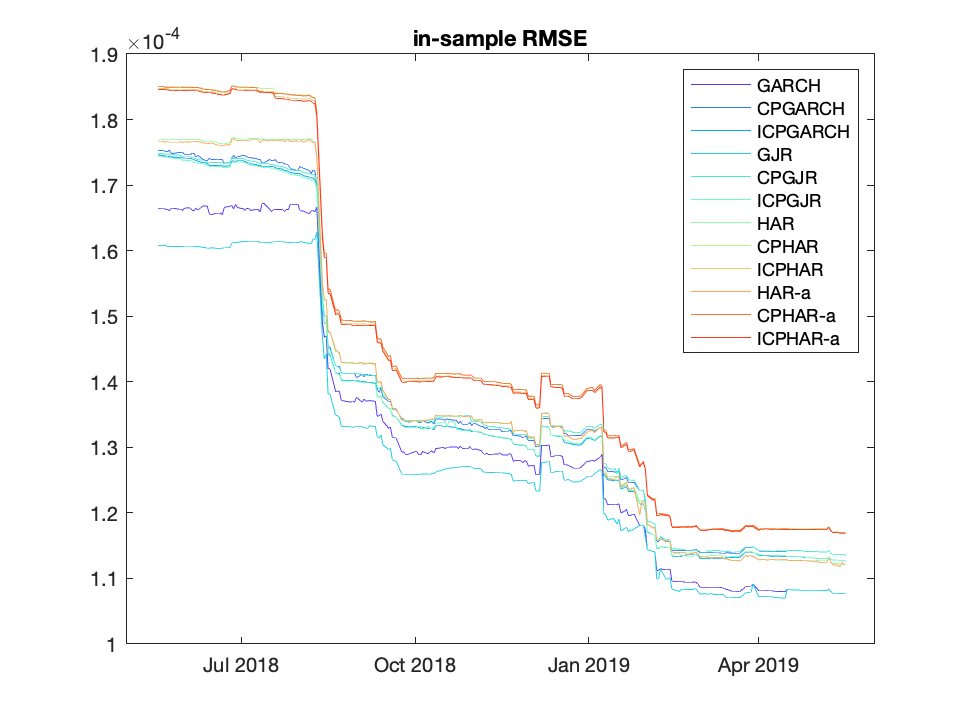

figure;
col=rainbow(12);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(7,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(8,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(9,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(12,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

#### MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))%mean(abs(sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)));mean(abs(sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)%mean((sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)).^2);mean((sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 12×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH           0.034401    0.041121
    CPGARCH         0.036612    0.041611
    ICPGARCH        0.036709     0.04174
    GJRGARCH        0.035535     0.04409
    CPGJRGARCH       0.03677    0.042133
    ICPGJRGARCH.    0.036678     0.04208
    HAR             0.014818     0.02006
    CPHAR           0.015171    0.020346
    ICPHAR          0.015171    0.020346
    HAR-a           0.014962    0.020148
    CPHAR-a         0.015273     0.02038
    ICPHAR-a        0.015301    0.020463


ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

#### DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(12,12);
for i=1:12
    for j=1:12
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 12×1 table
                  dm_test  
                ___________

    GARCH       1×12 double
    CPGARCH     1×12 double
    ICPGARCH    1×12 double
    GJR         1×12 double
    CPGJR       1×12 double
    ICPGJR      1×12 double
    HAR         1×12 double
    CPHAR       1×12 double
    ICPHAR      1×12 double
    HAR-a       1×12 double
    CPHAR-a     1×12 double
    ICPHAR-a    1×12 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 30456.528999 seconds.
